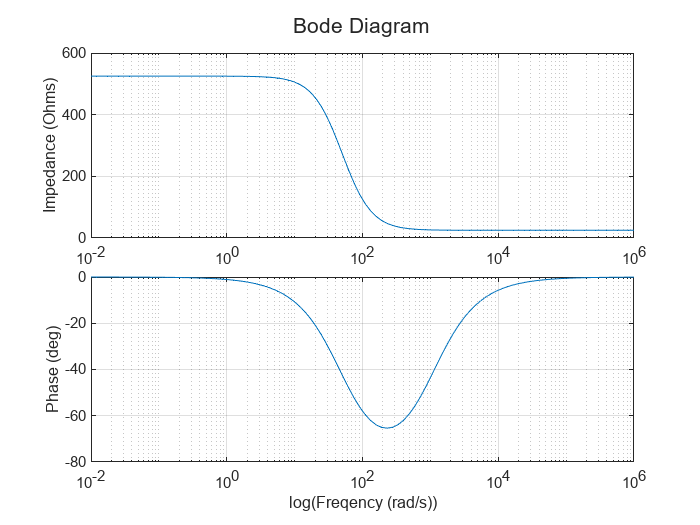

% Question 1a
close all

R_s = 25; % Ohm
R_ct = 500; % Ohm
C_dl = 40e-6; % F
R_par = (R_s*R_ct)/(R_s+R_ct);

freq = logspace(-2,6,100);

Z_faradaic = R_s*(1i*freq+(1/(R_par*C_dl)))./(1i*freq+(1/(R_ct*C_dl)));

tiledlayout(2,1,'TileSpacing','tight')

ax1 = nexttile;
semilogx(freq,real(Z_faradaic))
grid on
ylabel("Impedance (Ohms)");

ax2 = nexttile;
semilogx(freq,rad2deg(angle(Z_faradaic)))
grid on
xlabel("log(Freqency (rad/s))");
ylabel("Phase (deg)");

sgtitle("Bode Diagram")

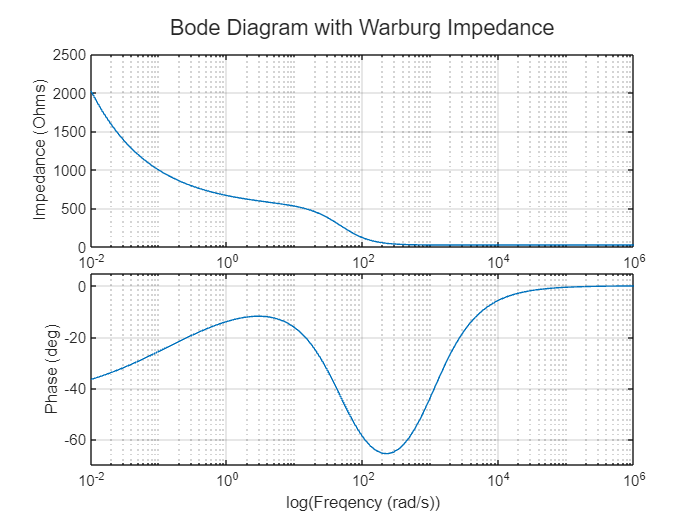

% Question 1b
close all

R_s = 25; % Ohm
R_ct = 500; % Ohm
C_dl = 40e-6; % F
warCoef = 150; % Ohm/s

freq = logspace(-2,6,100);

Z_w = warCoef*freq.^(-1/2).*(1-1i);

Z_1 = R_ct + Z_w;

Z_2 = (Z_1.*(1./(1i*freq*C_dl)))./(Z_1+(1./(1i*freq*C_dl)));

Z_faradaic = R_s + Z_2;

tiledlayout(2,1,'TileSpacing','tight')

ax1 = nexttile;
semilogx(freq,real(Z_faradaic))
grid on;
ylabel("Impedance (Ohms)");

ax2 = nexttile;
semilogx(freq,rad2deg(angle(Z_faradaic)))
grid on;
xlabel("log(Freqency (rad/s))");
ylabel("Phase (deg)"); ylim([-70 5]);

sgtitle("Bode Diagram with Warburg Impedance")

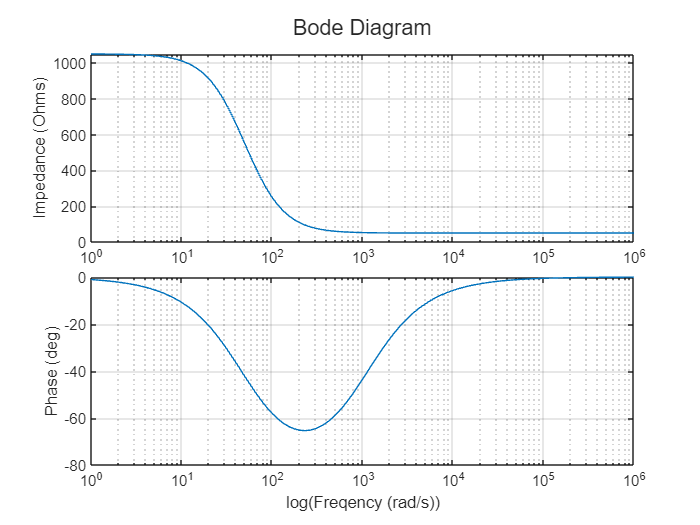

% Question 1c
close all

R_s = 50; % Ohm
R_ct = 1000; % Ohm
C_dl = 20e-6; % F
R_par = (R_s*R_ct)/(R_s+R_ct);

freq = logspace(0,6,100);

Z_faradaic = R_s*(1i*freq+(1/(R_par*C_dl)))./(1i*freq+(1/(R_ct*C_dl)));

tiledlayout(2,1,'TileSpacing','tight')

ax1 = nexttile;
semilogx(freq,real(Z_faradaic))
grid on
ylabel("Impedance (Ohms)");

ax2 = nexttile;
semilogx(freq,rad2deg(angle(Z_faradaic)))
grid on
xlabel("log(Freqency (rad/s))");
ylabel("Phase (deg)");

sgtitle("Bode Diagram")

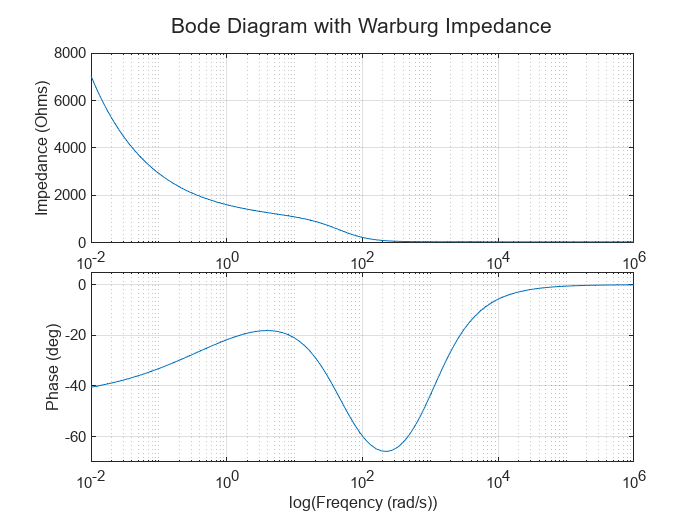

% Question 1d
close all

R_s = 50; % Ohm
R_ct = 1000; % Ohm
C_dl = 20e-6; % F
warCoef = 600; % Ohm/s

R_par = (R_s*R_ct)/(R_s+R_ct);

freq = logspace(-2,6,100);

Z_w = warCoef*freq.^(-1/2).*(1-1i);

Z_1 = R_ct + Z_w;

Z_2 = (Z_1.*(1./(1i*freq*C_dl)))./(Z_1+(1./(1i*freq*C_dl)));

Z_faradaic = R_s + Z_2;

tiledlayout(2,1,'TileSpacing','tight')

ax1 = nexttile;
semilogx(freq,real(Z_faradaic))
grid on;
ylabel("Impedance (Ohms)");

ax2 = nexttile;
semilogx(freq,rad2deg(angle(Z_faradaic)))
grid on;
xlabel("log(Freqency (rad/s))");
ylabel("Phase (deg)"); ylim([-70 5]);

sgtitle("Bode Diagram with Warburg Impedance")

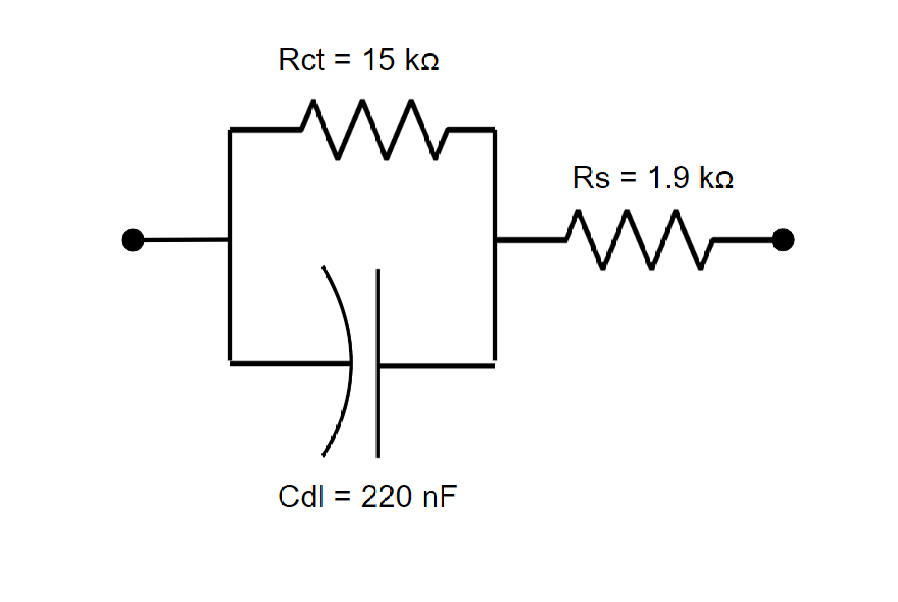

% Question 2a
close all
imshow("Randles_2a.png");

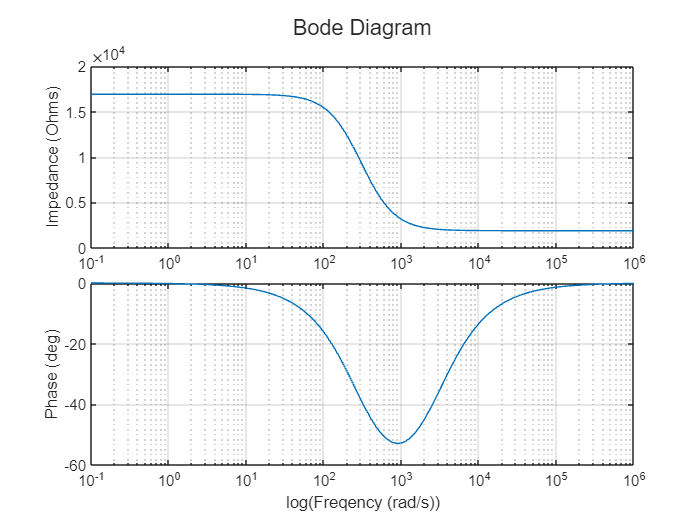

% Question 2b
close all

R_s = 1900; % Ohm
R_ct = 15000; % Ohm
C_dl = 220e-9; % F
R_par = (R_s*R_ct)/(R_s+R_ct);
freq = logspace(-1,6,100);

Z_faradaic = R_s*(1i*freq+(1/(R_par*C_dl)))./(1i*freq+(1/(R_ct*C_dl)));

tiledlayout(2,1,'TileSpacing','tight')

ax1 = nexttile;
semilogx(freq,real(Z_faradaic))
grid on
ylabel("Impedance (Ohms)");

ax2 = nexttile;
semilogx(freq,rad2deg(angle(Z_faradaic)))
grid on
xlabel("log(Freqency (rad/s))");
ylabel("Phase (deg)");

sgtitle("Bode Diagram")

% Question 2c

effAreaFactor = 3.8; % Given

% C_dl is directly proportional to the electrochemical surface area of the
% electrode, so eliminating the roughness would decrease C_dl by the
% effective area factor

C_dl = 220e-9; % F
C_dl_no_rough = C_dl / effAreaFactor % To be used in model

C_dl_no_rough = 5.7895e-08

% R_s is dependent on the geometric surface area, so eliminating roughness
% will have no effect on R_s

R_s = 1900; % Ohm
R_s_no_rough = R_s

R_s_no_rough = 1900

% R_ct is inversely proportional to the electrochemical surface area of the
% electrode, so eliminating the roughness would increase R_ct by the
% effective area factor

R_ct = 15000; % Ohm
R_ct_no_rough = R_ct*effAreaFactor

R_ct_no_rough = 57000

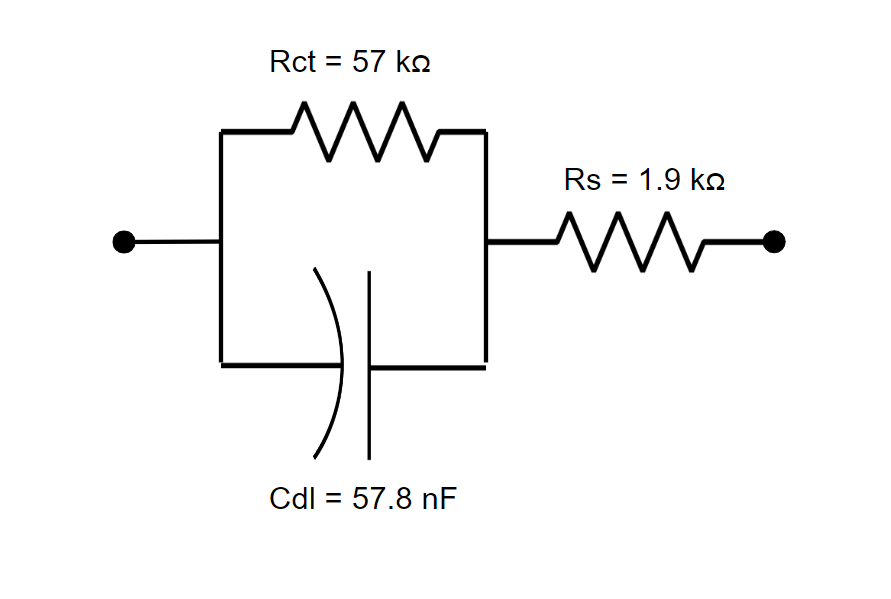

close all
imshow("Randles_2c.png")

% Question 3a
close all

% Prior to reading in the table, I removed all of the diagnostic
% information from above the data.
pt_Data = readtable('be260-hw2-2020-fall-cv-platinum.csv');

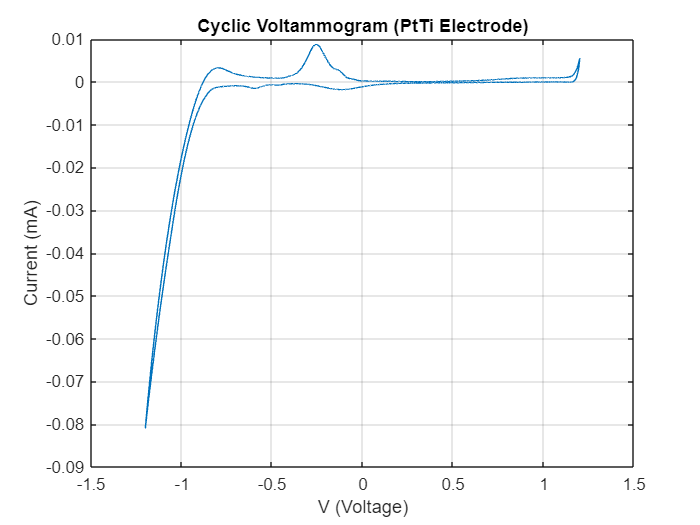

V = table2array(pt_Data(:,'Ewe_V'));
I = table2array(pt_Data(:,'x_I__mA'));

plot(V,I)
grid on;
xlabel('V (Voltage)');
ylabel('Current (mA)');
title("Cyclic Voltammogram (PtTi Electrode)");

cumQ = rmmissing(cumtrapz(V,I)); % Computes the area under the curve
                                 % rmmissing removes all NaN values that
                                 % are emerging for unknown reasons
Q = cumQ(end)

Q = 0.0053

% The overall charge Q corresponding to its opening is 0.0027 mC

% Question 3b

ptElectrodeEffectiveArea = Q / 210 % (mC) / (mC cm^-2) = cm^2

ptElectrodeEffectiveArea = 2.5406e-05

% Using Q = 0.0053 from 3(a), the effective area of the electrode would be
% 0.0000254 cm^2. The effective area provided from problem 2 was 0.002603
% cm^2. This value is 3 magnitudes larger than the calculated effective
% area in problem 3b. This implies that one or several dimensions of the
% electrode used to record the above data were significantly smaller than
% the dimensions of the electrode from problem 2.

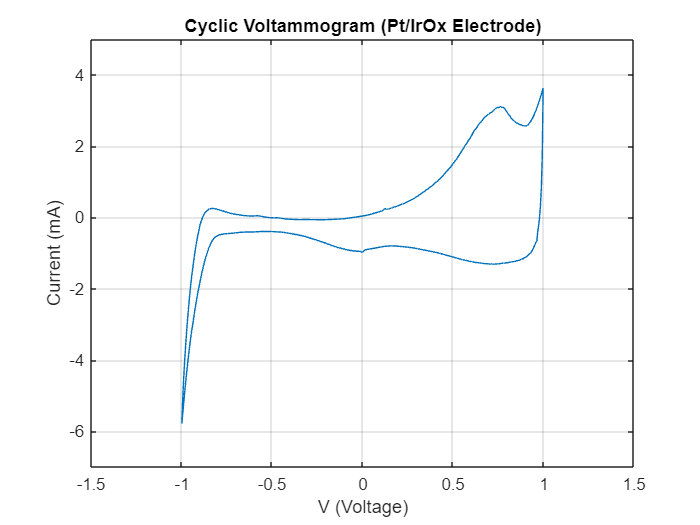

% Question 3c

% Prior to reading the data, I deleted the all sheets except for the one
% titled Ir_Pt_IV
ptIrox_Data = readtable('be260-hw2-2022-fall-cv-irox.xlsx');
I = table2array(ptIrox_Data(:,"Column2"));
V = table2array(ptIrox_Data(:,"Column1"));

plot(V,I)
grid on;
xlabel('V (Voltage)'); xlim([-1.5 1.5]);
ylabel('Current (mA)'); ylim([-7 5]);
title("Cyclic Voltammogram (Pt/IrOx Electrode)");

Q = trapz(V,I) % Computes the area under the curve

Q = 3.2775

ptIrOxElectrodeEffectiveArea = Q / 210 % (mC) / (mC cm^-2) = cm^2

ptIrOxElectrodeEffectiveArea = 0.0156

% Using Q = 3.2775 mC from above, the effective area of the electrode would be
% 0.0156 cm^2.

% The effective area of this electrode (0.0156 cm^2) is much closer to the
% effective area of the electrode from problem 2 (0.00260 cm^2). Since
% there is only ~1 magnitude of difference between these effective areas,
% it is reasonable to assume that the addition of the IrOx layer
% substantially increased the effective surface area of the Pt electrode
% from problem 3a.

% The overall charge and therefore the effective area of the electrode are
% both larger for the IrOx-coated Pt electrode than the Pt electrode alone. 
% This makes sense because an increase in surface area directly correlates
% with an increased capacitance.

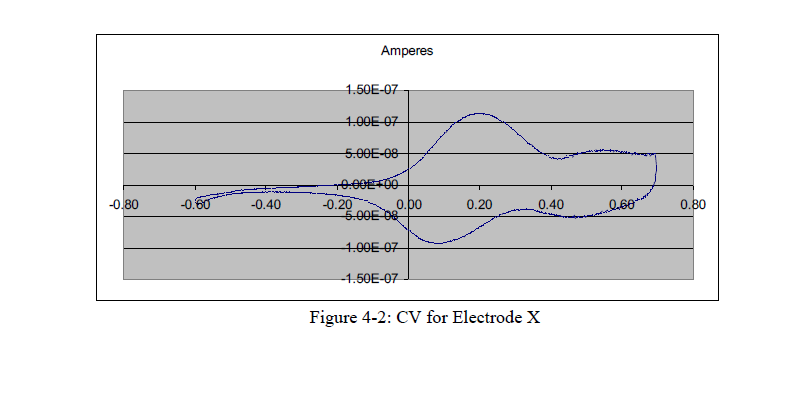

% Question 4a
imshow('Screenshot 2022-10-15 123542.png')

% Two measurements can behave differently if the reaction occuring at the 
% electrode-electrolyte interface is irreversible. These types of reactions
% will have a time-dependent decaying rate constant. Some example of
% irreversible Faradaic reactions include: (1) reduction of water, (2)
% oxidation of water, (3) corrosion of Pt, (4) gas evolution, or (5) anodic
% dissolution.

% Question 4b
imshow('Screenshot 2022-10-15 123542.png')

% The water window is the range of potentials applied to generate the CV
% Voltammogram. In the above figure, the water window appears to be roughly
% [-0.6V 0.68V].

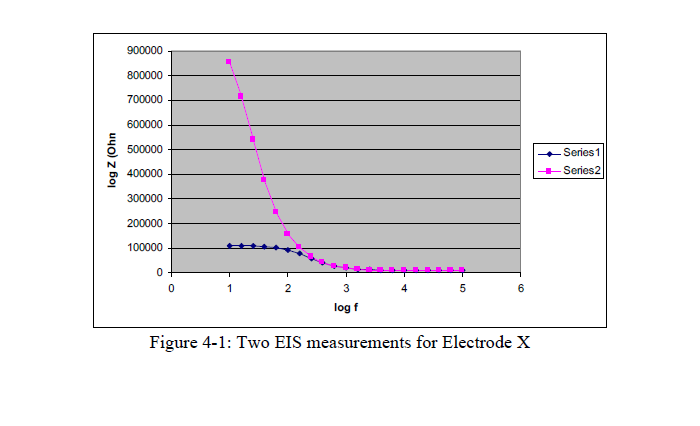

% Question 4c
close all
imshow("Screenshot 2022-10-15 130721.png")

% The pole of this figure defines the value R_S + R_{ct} and the zero of
% this figure defines the value R_S. In this case, the pole is at roughly
% log f = 1 and the zero is at roughly log f = 3.5. Therefore, R_S = 10
% kOhm and R_S + R_{ct} = 110 kOhm, so R_{ct} = 100 kOhm. The pole of 10e2
% equals the expression 1/(R_{ct}*C_{dl}). We know R_{ct}, so the only
% unknown is C_{dl}, which we can solve for:

% logf = 1/(R_{ct}*C_{dl})
% C_{dl} = 1/(logf*R_{ct})
% C_{dl} = 1/((log2)*(1e5))
C_dl = 1/((1e2)*(1e5)) % F

C_dl = 1.0000e-07

% Therefore, R_{ct} = 90 kOhm, R_S = 10 kOhm, and C_{dl} = 33 uF.

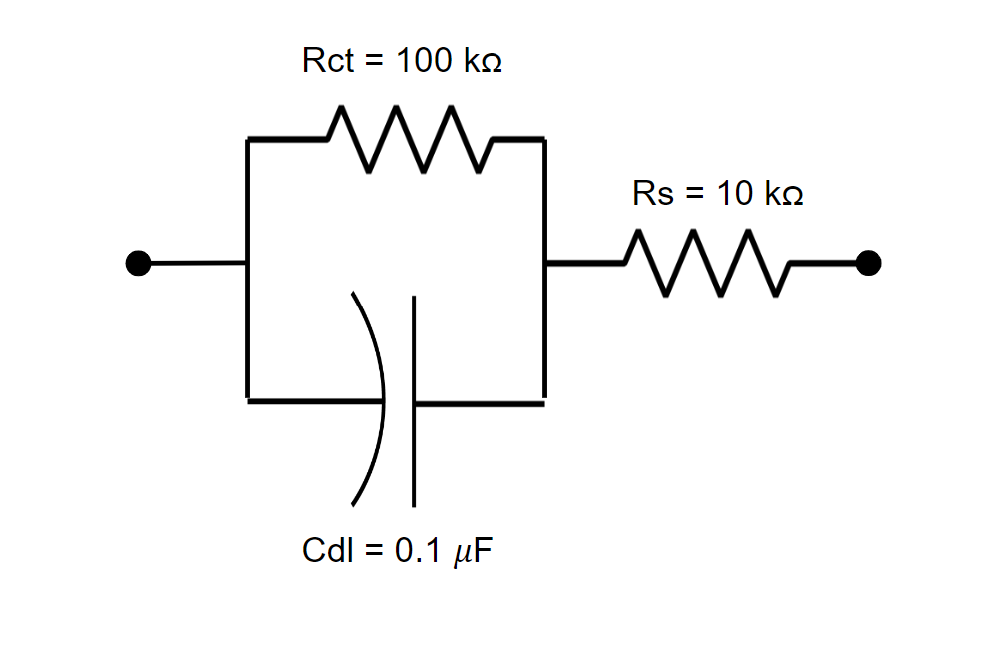

% Question 4d
close all
imshow("Randles_4d.png")

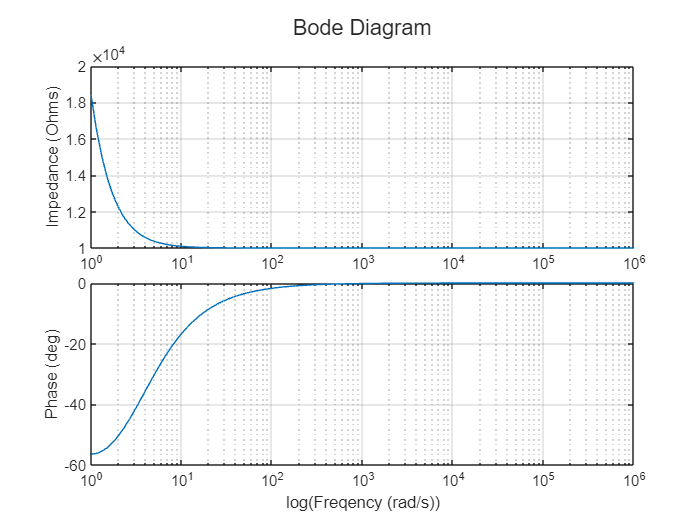

% Question 4e
close all

R_s = 10000; % Ohm
R_ct = 100000; % Ohm
C_dl = 33e-6; % F
R_par = (R_s*R_ct)/(R_s+R_ct);

freq = logspace(0,6,100);

Z_faradaic = R_s*(1i*freq+(1/(R_par*C_dl)))./(1i*freq+(1/(R_ct*C_dl)));

tiledlayout(2,1,'TileSpacing','tight')

ax1 = nexttile;
semilogx(freq,real(Z_faradaic))
grid on
ylabel("Impedance (Ohms)");

ax2 = nexttile;
semilogx(freq,rad2deg(angle(Z_faradaic)))
grid on
xlabel("log(Freqency (rad/s))");
ylabel("Phase (deg)");

sgtitle("Bode Diagram")

% Question 5a
close all

% Definition of given parameters
rho = 560; % Ohm*s (Retina Tissue Resitivity)
r_elec = 50e-4; % cm (Radius of microelectrode)
C_dl_orig = 54.5e-6; %F/cm^2 (Original double layer capacitance)
R_ct_orig = 5.1e4; % Ohms*m^-2 (Original charge transfer resistance)

roughness_factor = 40;

% Since the electrode is circular and R_s ignores roughness, R_s can be found 
% via the equation: R_S = rho / 4r
R_S_a = rho/(4*r_elec) % Ohm

R_S_a = 28000

% Since C_dl is directly proportional to the electrode surface area,
% increasing the roughness of the area by a factor of 40x would also
% increase C_dl by a factor of 40, so
C_dl_a = C_dl_orig*40*pi*r_elec^2

C_dl_a = 1.7122e-07

% Since R_ct is inversely proportional to the electrode surface area,
% increasing the roughness of the area by a factor of 40x would
% decrease R_ct by a factor of 40, so
R_ct_a = R_ct_orig/(40*pi*r_elec^2)

R_ct_a = 1.6234e+07

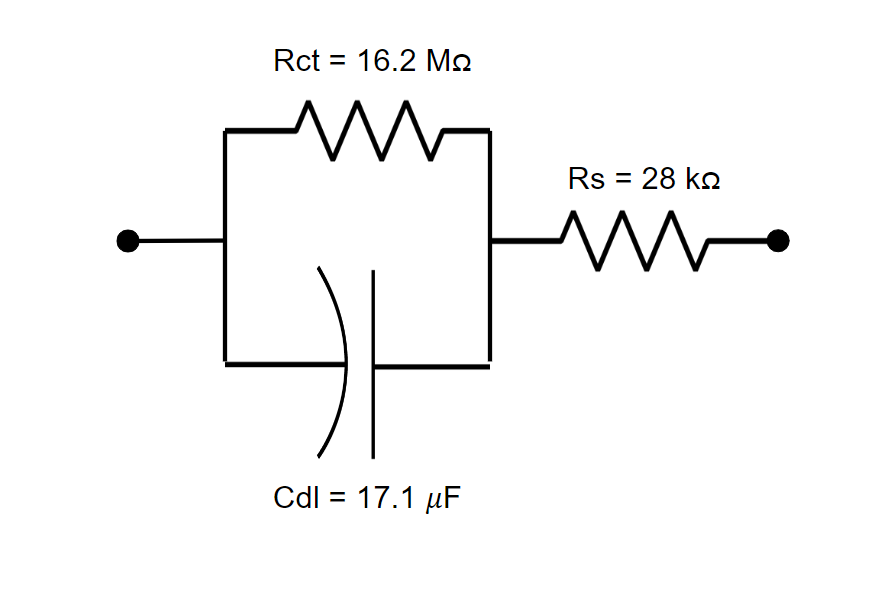

imshow("Randles_5a.png")

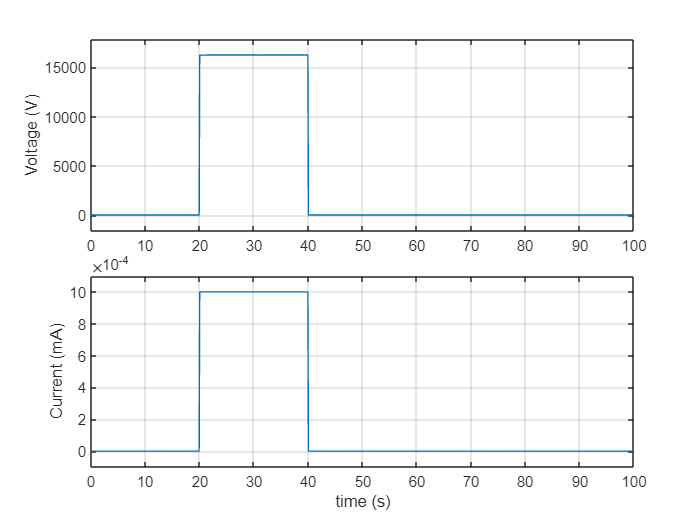

close all
% 5.a.4
% V    = IZ
% V(S) = (I/S)*(Rs+(Rct||(1/(S*Cdl))))
% V(S) = (I/S)*(Rs+(Rct/(Rct*S*Cdl+1)))
% V(S) = Rs*(I/S)+Rct*(I/S)/(Rct*S*Cdl+1)
% V(t) = I*Rs + I*Rct*(1-exp(-t/(Rct*Cdl)))

% (TODO) 5.a.5
t = linspace(0,100,1000);
cStart = 20;
cEnd = 40;
cAmp = 1e-3; % Amp
I = Iovertime(t,cStart,cEnd,cAmp);

V = I*R_S_a + I*R_ct_a.*(1-exp(-t/(R_ct_a*C_dl_a)));

tiledlayout(2,1,'TileSpacing','tight')

ax1 = nexttile;
plot(t,V)
grid on
ylabel("Voltage (V)"); ylim([-0.1*max(V) max(V)*1.1])

ax2 = nexttile;
plot(t,I)
grid on
xlabel("time (s)");
ylabel("Current (mA)"); ylim([-0.1*cAmp cAmp*1.1])

% Question 5b

% Since R_S is dependent on geometric surface area, decreasing the surface
% area by 10% would decrease R_s_b by 10%
R_S_b = R_S_a*0.9

R_S_b = 25200

% Since C_dl is directly proportional to the electrode surface area,
% decreasing the surface area by 10% would decrease C_dl by 10%:
C_dl_b = C_dl_a*0.9

C_dl_b = 1.5410e-07

% Since R_ct is inversely proportional to the electrode surface area,
% decreasing the surface area by 10% would increase C_dl by 10%:
R_ct_b = R_ct_a*1.1

R_ct_b = 1.7857e+07

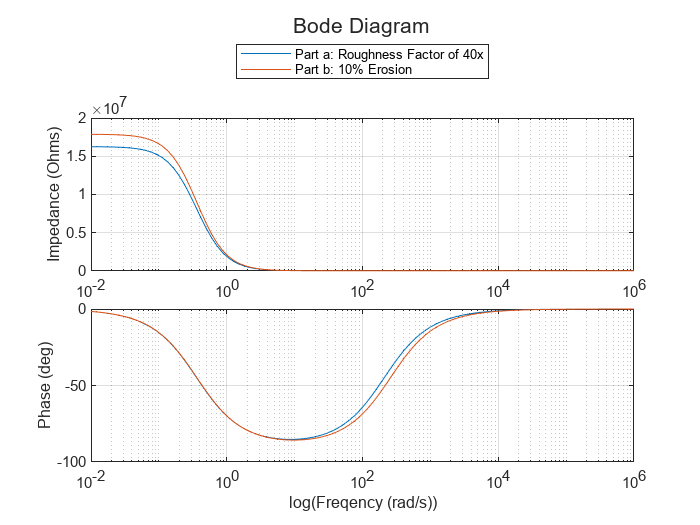

% Question 5c
close all

R_par_a = (R_S_a*R_ct_a)/(R_S_a+R_ct_a);
R_par_b = (R_S_b*R_ct_b)/(R_S_b+R_ct_b);

freq = logspace(-2,6,100);

Z_ct_a = R_S_a*(1i*freq+(1/(R_par_a*C_dl_a)))./(1i*freq+(1/(R_ct_a*C_dl_a)));
Z_ct_b = R_S_b*(1i*freq+(1/(R_par_b*C_dl_b)))./(1i*freq+(1/(R_ct_b*C_dl_b)));

tiledlayout(2,1,'TileSpacing','tight')

ax1 = nexttile;
semilogx(freq,real(Z_ct_a))
hold on
semilogx(freq,real(Z_ct_b))
grid on
ylabel("Impedance (Ohms)");
hold off

ax2 = nexttile;
semilogx(freq,rad2deg(angle(Z_ct_a)))
hold on
semilogx(freq,rad2deg(angle(Z_ct_b)))
grid on
xlabel("log(Freqency (rad/s))");
ylabel("Phase (deg)");
hold off

lg = legend('Part a: Roughness Factor of 40x','Part b: 10% Erosion');
lg.Layout.Tile = 'north';

sgtitle("Bode Diagram")